## Naïve Bayes Code Tests

clear
clc
clf
close all
% loads the letter dataset into letterDatasetNormalised and
% letterDatasetNotNormalised
load letterDatasetClass.mat
letterDataset = letterDatasetNotNormalised;

### Analysis from a Naïve Bayes perspective

% get a default model
nBayes = NBayesClass(letterDataset)

nBayes =   NBayesClass with properties:

    randomSeed: 300
         debug: 1
       dataset: [1×1 LetterDatasetClass]
     distNames: {'kernel'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'kernel'  'mvmn'  'mvmn'  'mvmn'  'kernel'  'mvmn'  'kernel'  'kernel'  'kernel'  'kernel'  'mvmn'}


[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
model = nBayes.simpleNaiveBayesClassifier()

Training loss: 0.35 Test loss: 0.37


model =   ClassificationNaiveBayes
            PredictorNames: {'xBox'  'yBox'  'width'  'height'  'onPixelCount'  'xBar'  'yBar'  'x2Bar'  'y2Bar'  'xyBar'  'x2yBr'  'xy2Br'  'xEge'  'xEgvy'  'yEge'  'yEgvx'}
              ResponseName: 'TargetAscii'
     CategoricalPredictors: []
                ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
            ScoreTransform: 'none'
           NumObservations: 16000
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {26×16 cell}


  Properties, Methods


Set prior distribution to an empirical distribution

freqDist = cell2table(tabulate(Y));
prior = freqDist{:,3};
model.Prior = prior;
cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.02f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.36


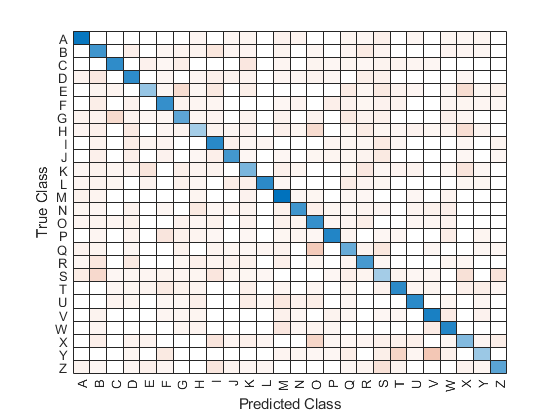

[predicted, score] = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predicted);

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames);

  Columns 1 through 8

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 9 through 16

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}



model.DistributionNames = {'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', ...
  'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', 'kernel', };

You cannot set the read-only property 'DistributionNames' of ClassificationNaiveBayes.

Error in classreg.learning.internal.DisallowVectorOps/subsasgn (line 34)
                [varargout{1:nargout}] = builtin('subsasgn',this,s,data);

predictions = resubPredict(model);
confusionMat = confusionchart(Y, predictions);
